# Some interesting scripts that could be used to test forward kinematics.

## Set up the data classes

close
clear
clc
obj = UpperLimbModelToolbox();

ans =
     []
ans =
     []


## Some basic kinematic usage

shuffle the configuration

q_init = [3 ; 0.2; 0; 1; 1; 0.2; 1]

q_init =     3.0000
    0.2000
         0
    1.0000
    1.0000
    0.2000
    1.0000


calculate the forward kinematics

T_frame = obj.forwardKinematics(q_init);
w_p = T_frame(1:3,4)

w_p =     0.2256
   -0.4976
    0.0223


w_R = T_frame(1:3,1:3)

w_R =     0.5410   -0.0107    0.8409
    0.5721    0.7376   -0.3586
   -0.6165    0.6751    0.4052


calculate the jacobian

jacobian = obj.getGeometricJacobian(q_init)

jacobian =    -0.1013    0.0231   -0.0255    0.2206   -0.0410    0.0038   -0.0842
   -0.0462    0.1809    0.0574    0.2365   -0.0731   -0.0015    0.0365
   -0.0151   -0.4894   -0.2340    0.0277    0.0569    0.0164   -0.0486
    0.0165    0.9966   -0.0117    0.0488   -0.8572   -0.0188    0.5765
    0.0282   -0.0083    0.9709   -0.1610    0.5134   -0.6215    0.5335
   -0.1970    0.0824    0.2394    0.9858    0.0411   -0.6056   -0.6056


## A open-loop jacobian control example

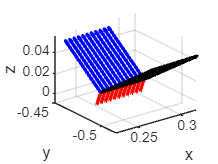

figure();
q = q_init;
x = [0.0005; 0 ; 0; 0; 0;0];
for i = 0: 100
    if mod(i, 10) == 0
        T_frame = obj.forwardKinematics(q);
        w_p = T_frame(1:3,4);
        w_R = T_frame(1:3,1:3);
        obj.model.plot_frame(w_p, w_R, 0.05);
    end
    
    J = obj.getGeometricJacobian(q);
    q = q + pinv(J) *x;
end


w_p

w_p =     0.2762
   -0.4976
    0.0229


## A close loop inverse kinematic solver (with Jacobian)

figure();
q_value = q_init;

T = obj.forwardKinematics(q_init);

T_d = eye(4);
T_d(1:3,4) = T(1:3,4) + [-0.03; 0.02; 0.01];
T_d(1:3,1:3) = eul2rotm([0.5; 0.2; 0.3]') * T(1:3,1:3) ;

T

T =     0.5410   -0.0107    0.8409    0.2256
    0.5721    0.7376   -0.3586   -0.4976
   -0.6165    0.6751    0.4052    0.0223
         0         0         0         0


obj.model.plot_frame(T(1:3,4), T(1:3,1:3), 0.05);

T_d

T_d =     0.0428   -0.1010    0.9940    0.1956
    0.8537    0.5205    0.0162   -0.4776
   -0.5190    0.8479    0.1085    0.0323
         0         0         0    1.0000


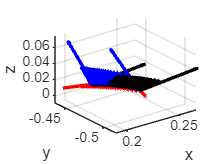

obj.model.plot_frame(T_d(1:3,4), T_d(1:3,1:3), 0.05);


for iIter = 1:1000
    T_s = obj.forwardKinematics(q_value);
    obj.model.plot_frame(T_s(1:3,4), T_s(1:3,1:3), 0.02);
    
    e = zeros(6,1);
    e(1:3) = T_d(1:3,4) - T_s(1:3,4);
    e(4:6) = logmapR(T_d(1:3, 1:3) * T_s(1:3,1:3)');
    e(1:3) = 0.1 * e(1:3);
    e(4:6) = 0.01 * e(4:6);

    % stop when tolerance satisfied
    if all( abs(e) <= [1e-3 * ones(3,1); 1e-3 * ones(3,1)])
        break
    end

    J = obj.getGeometricJacobian(q_value);

    J_inv = pinv(J);
    delta_q = 1 * J_inv * e;
    q_value = q_value + delta_q;
end


w_p = T_s(1:3,4)

## Close loop inverse kinematic solver (from toolbox)

% figure();
% T = obj.forwardKinematics(q_init);
% 
% T_d = eye(4);
% T_d(1:3,4) = T(1:3,4) + [-0.01; 0.01; 0];
% T_d(1:3,1:3) = T(1:3,1:3) * eul2rotm([0.1; 0.2; 0.05]');
% x_d = x + [-0.01; 0.01; 0; 0.1; 0.2; 0.05];
% 
% T_d
% obj.model.plot_frame(T_d(1:3,4), T_d(1:3,1:3), 0.05);
% T
% obj.model.plot_frame(T(1:3,4), T(1:3,1:3), 0.05);
% 
% [q,info] = obj.model.IK_numeric(obj.coord_list, 1, x_d)
% 
% T_fin = obj.forwardKinematics(q);
% obj.model.plot_frame(T_fin(1:3,4), T_fin(1:3,1:3), 0.03);